

data_sol9 = load('calib_BI_quad9.dat');
I9 = data_sol9(:,1);
B9 = data_sol9(:,2); %magnetic radius 20 mm

data_sol8 = load('calib_BI_quad8.dat');
I8 = data_sol8(:,1);
B8 = data_sol8(:,2); %magnetic radius 20 mm

data_sol22 = load('calib_BI_quad22.dat');
I22 = data_sol22(:,1);
B22 = data_sol22(:,2); %magnetic radius 20 mm
%%


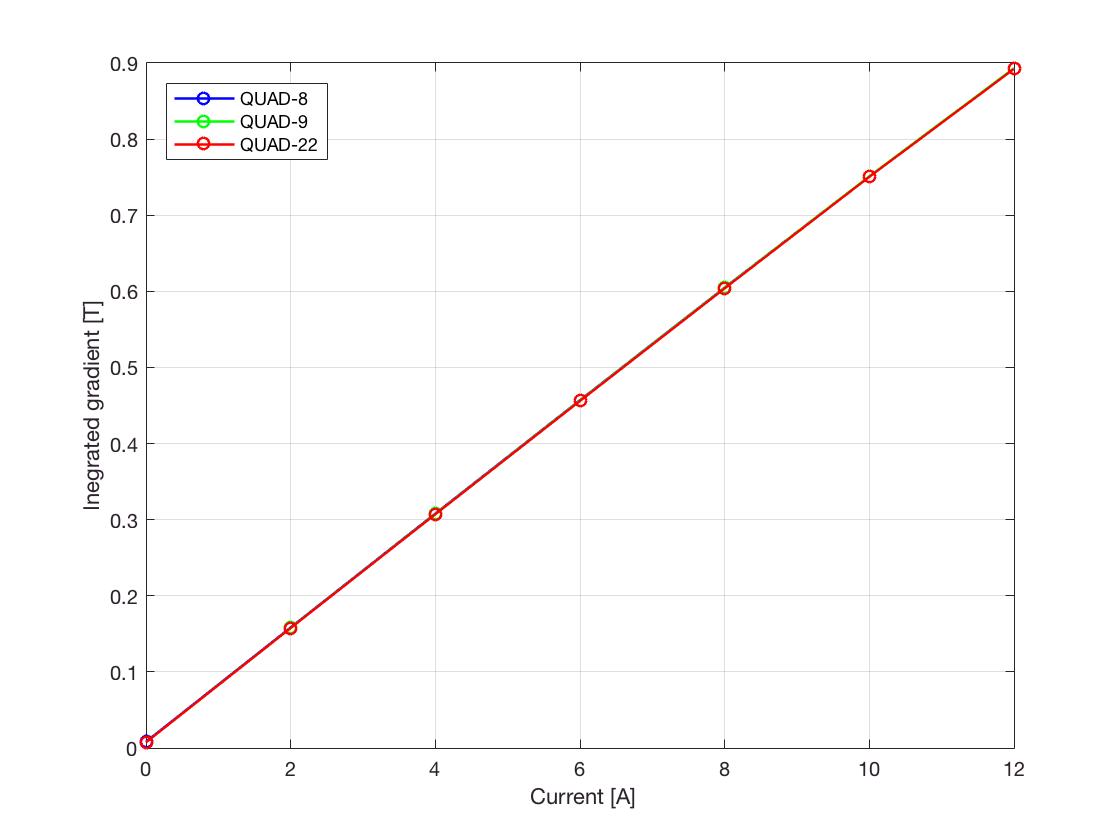

figure
set(gca,'FontSize',20)
plot(I8, B8, 'bo-', 'MarkerSize',6, 'LineWidth',1.2)
hold on
plot(I9, B9, 'go-', 'MarkerSize',6, 'LineWidth',1.2)
plot(I22, B22, 'ro-', 'MarkerSize',6, 'LineWidth',1.2)
hold off
xlabel(' Current [A]')
ylabel('Inegrated gradient [T]')
u = legend('QUAD-8','QUAD-9', 'QUAD-22');
set(u,'Location','NorthWest')

%%


B = [B8'; B9'; B22'];
Bmean = mean(B);
Bstd = std(B);
sizeB = size(B);
entries = sizeB(1,1);

% figure(2)
% set(gca,'FontSize',18)
% errorbar(I8,Bmean,Bstd./sqrt(entries),'k.-','MarkerSize',16, 'LineWidth',1.3)
% xlabel(' Current [A]')
% ylabel('Inegrated gradient [T]')

table(I8,B8,B9,B22,Bmean',Bstd',Bstd'./Bmean', Bstd'./sqrt(entries) , Bstd'./(sqrt(entries).*Bmean'),'VariableNames',{'I','B8','B9','B22','Bmean','Bstd','RelError','MeanError','RelMeanError'})

ans =     I         B8             B9             B22              Bmean                  Bstd                  RelError               MeanError              RelMeanError    
    __    ___________    ___________    ___________    _________________    ____________________    ____________________    ____________________    ____________________

     0    0.008316438    0.007610962    0.007428731          0.007785377    0.000468851120965921       0.060222018916479    0.000270691320899532      0.0347691988325719
     2    0.158431591    0.157906423    0.157600036           0.15797935    0.000420546893940504     0.00266203712029771    0.000242802862423411     0.00153692784799666
     4    0


%%


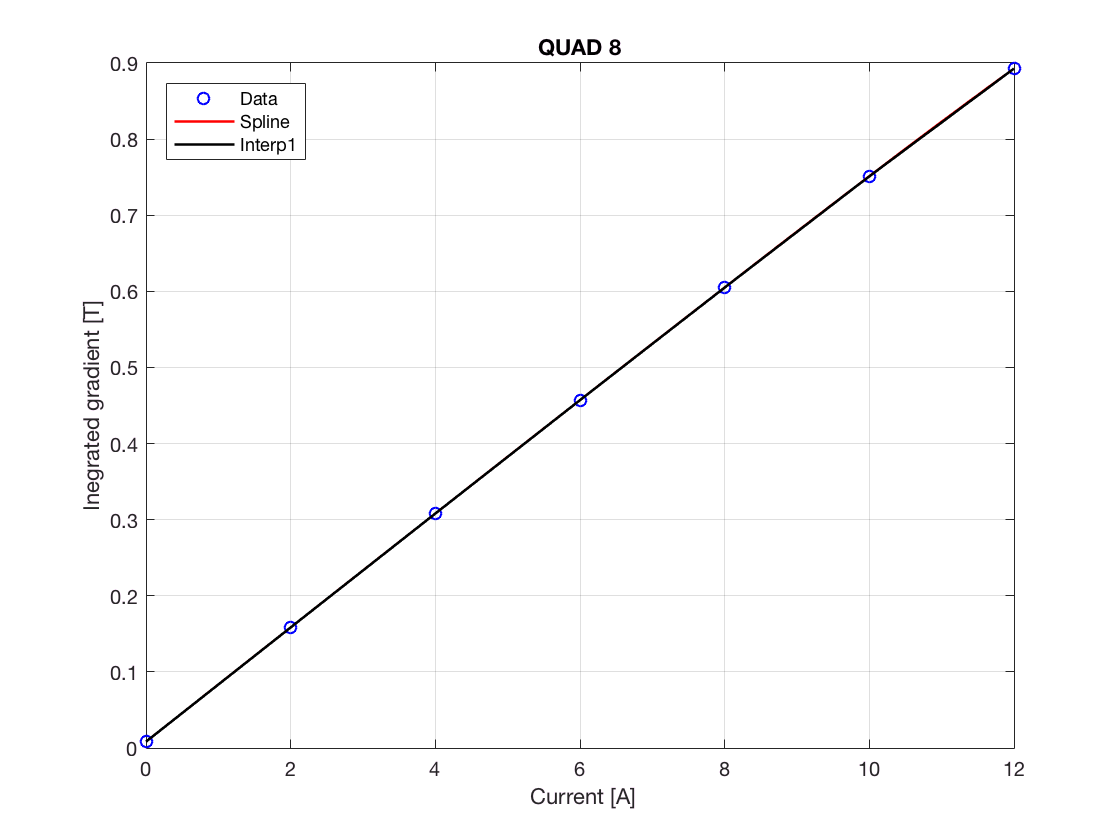

xx8 = linspace(min(I8),max(I8),5*length(I8));
yy8 = spline(I8,B8,xx8);
ii8 = interp1(I8,B8,xx8); 

figure
set(gca,'FontSize',20)
plot(I8, B8, 'bo', 'MarkerSize',6)
hold on
plot(xx8, yy8, 'r-', 'Linewidth',1.3)
plot(xx8, ii8, 'k-', 'Linewidth',1.3)
hold off
title('QUAD 8')
xlabel(' Current [A]')
ylabel('Inegrated gradient [T]')
u = legend('Data','Spline', 'Interp1');
set(u,'Location','NorthWest')


%% Polynomial fit

p8 = polyfit(I8,B8,7)

p8 =   -0.000000004712720   0.000000150422831  -0.000001879121024   0.000011113027922  -0.000034956919042                   0   0.075134053972676   0.008316438000000



%x = linspace(min(I8),max(I8),3*length(I8));
f8 = polyval(p8,xx8);

%T8 = table(I8,B8,interp1(x,f8,I8),B8-interp1(x,f8,I8),100*(interp1(x,f8,I8) - B8)./B8,'VariableNames',{'I','B','Fit','FitError','RelFitError'})
T8 = table(I8,B8,polyval(p8,I8),B8-polyval(p8,I8),100*(polyval(p8,I8) - B8)./B8,'VariableNames',{'I','B','Fit','FitError','RelFitError'});

% Linear fit
p81 = polyfit(I8,B8,1)

p81 =    0.073848756142857   0.011300182285714



f81 = polyval(p81,xx8);

T81 = table(I8,B8,polyval(p81,I8),B8-polyval(p81,I8),100*(polyval(p81,I8) - B8)./B8,'VariableNames',{'I','B','Fit','FitError','RelFitError'})

T81 =     I          B                Fit                  FitError              RelFitError    
    __    ___________    __________________    _____________________    __________________

     0    0.008316438    0.0113001822857142     -0.00298374428571423      35.8776712543788
     2    0.158431591     0.158997694571428    -0.000566103571428472     0.357317355620365
     4    0.308075045     0.306695206857143      0.00137983814285725     -0.44789026740457
     6    0.457059374     0.454392719142857      0.00266665485714301    -0.583437296954556
     8    0.604984004     0.602090231428571      0.00289377257142864    -0.478322162618475
    10    0.751213865     0.749787743714286       0.0014261212857144    -0.189842247615384
    12    0.892668717           0.897485256      -0.0048165389999999     0.539566236418241


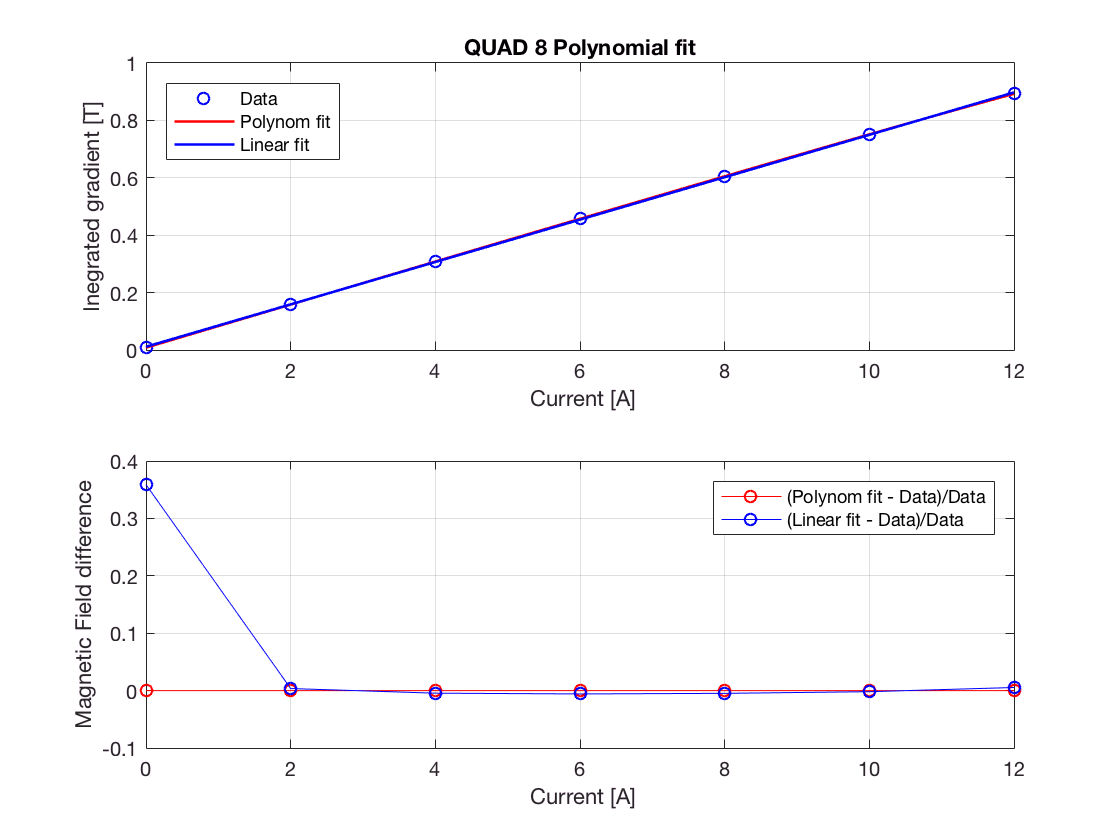



figure
subplot(2,1,1);
set(gca,'FontSize',20)
plot(I8, B8, 'o', 'MarkerSize',6)
hold on
plot(xx8, f8, 'r-', 'LineWidth',1.3)
plot(xx8, f81, 'b-', 'LineWidth',1.3)
hold off
title('QUAD 8 Polynomial fit')
xlabel(' Current [A]')
ylabel('Inegrated gradient [T]')
u = legend('Data','Polynom fit','Linear fit');
set(u,'Location','NorthWest')
subplot(2,1,2);
set(gca,'FontSize',20)
% plot(I8,(interp1(x,f8,I8) - B8)./B8,'ro-',...
%      I8,(interp1(x,f81,I8) - B8)./B8,'bo-');
plot(I8,(polyval(p8,I8) - B8)./B8,'ro-',...
     I8,(polyval(p81,I8) - B8)./B8,'bo-');
 xlabel(' Current [A]')
ylabel('Magnetic Field difference')
u = legend('(Polynom fit - Data)/Data','(Linear fit - Data)/Data');
set(u,'Location','NorthEast')

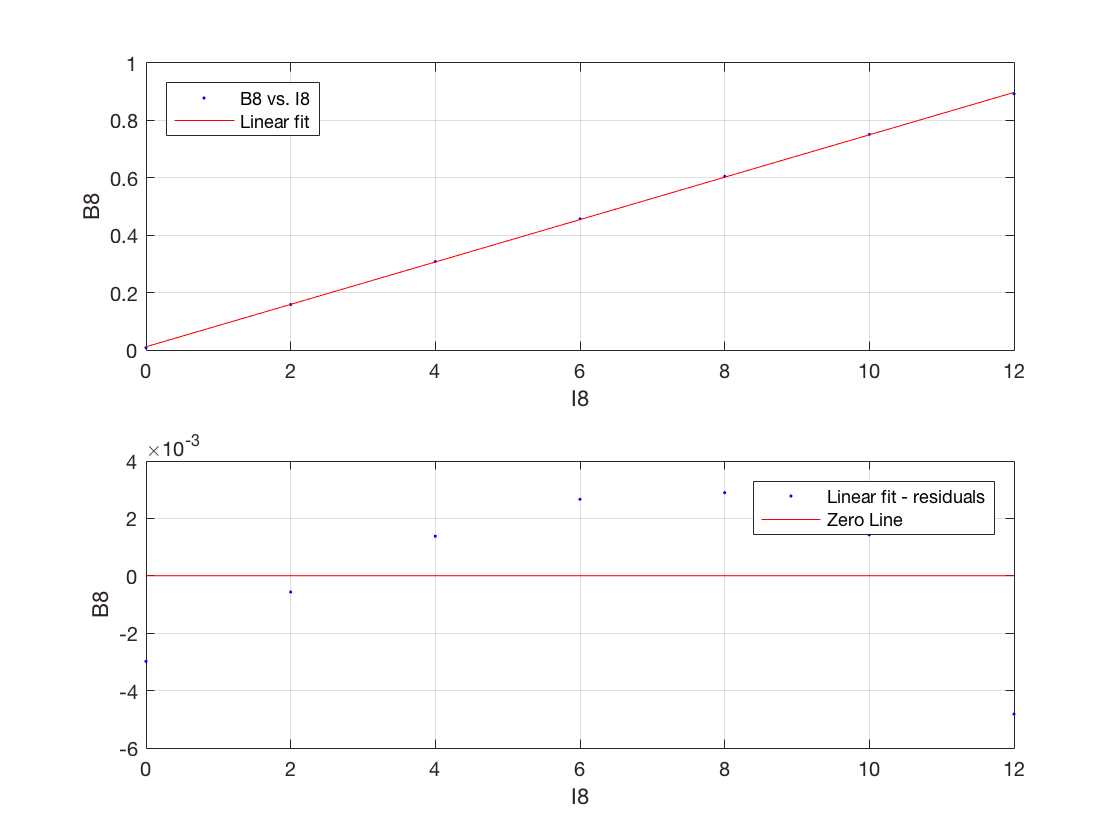

%% Linear fit

[fitresult, gof] = createFit(I8, B8);


x = linspace(min(I8),max(I8),3*length(I8));
fdata = feval(fitresult,x);

fitparam = coeffvalues(fitresult)

fitparam =    0.073848756142857   0.011300182285714


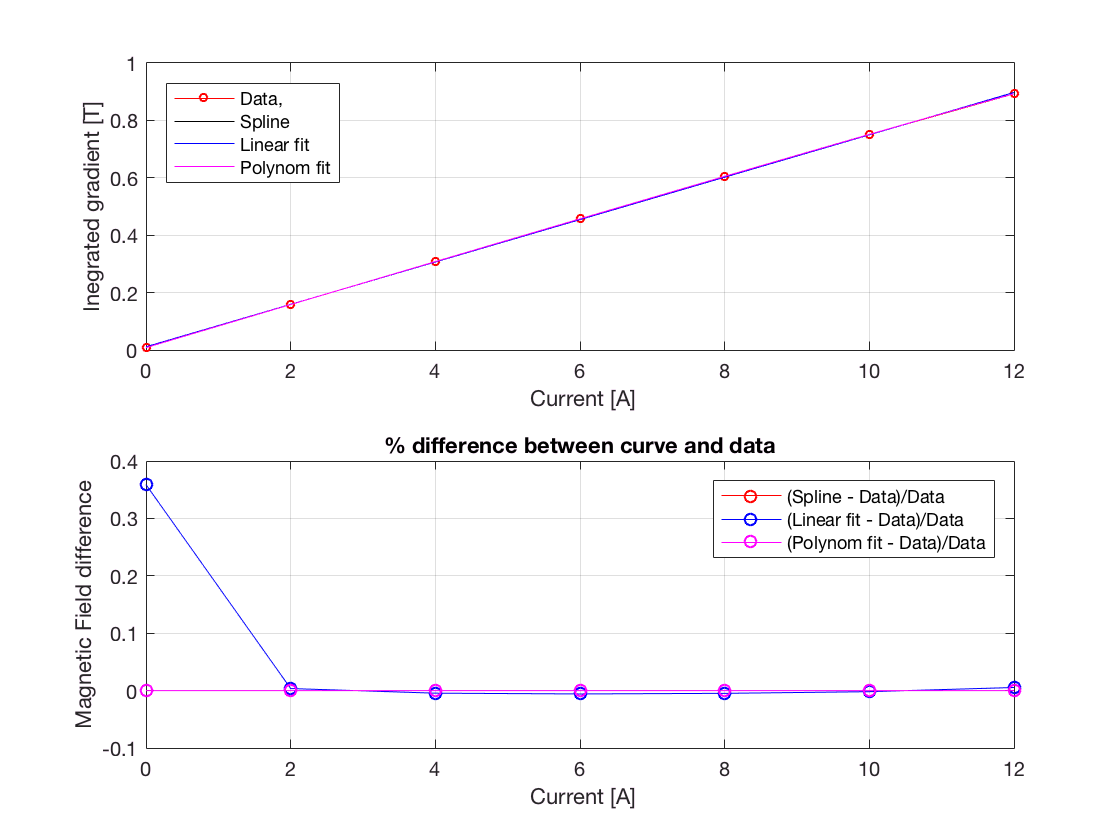

%% Linear, Polynomial fit and spline

% Try just using spline for all data points.
B_spline = spline(I8,B8,xx8); %pchip
B_linear = f81;

figure;
subplot(2,1,1);
plot(I8,B8,'-ro',xx8, B_spline,'k',xx8,B_linear,'b',xx8,f8,'m','MarkerSize',4);
u=legend('Data,','Spline','Linear fit','Polynom fit');
set(u,'Location','NorthWest')
xlabel(' Current [A]')
ylabel('Inegrated gradient [T]')
subplot(2,1,2);
% plot(I8,(interp1(xx8,B_spline,I8) - B8)./B8,'ro-',...
%      I8,(interp1(xx8,B_linear,I8) - B8)./B8,'bo-',...
%      I8,(interp1(xx8,f8,I8) - B8)./B8,'mo-');
plot(I8,(spline(xx8,B_spline,I8) - B8)./B8,'ro-',...
     I8,(polyval(p81,I8) - B8)./B8,'bo-',...
     I8,(polyval(p8,I8) - B8)./B8,'mo-');
u = legend('(Spline - Data)/Data','(Linear fit - Data)/Data','(Polynom fit - Data)/Data');
set(u,'Location','NorthEast')
xlabel(' Current [A]')
ylabel('Magnetic Field difference')
title('% difference between curve and data');


%%


k2amp('QP2','Monitor',9.2625,[1 2], 0.05)

ans =    3.006378571819553


amp2k('QP2','Monitor',10,[1 2], 0.05)

ans =   30.045477493890534
